# 3.2 Simple Bandpass Filter Design

clc,clear
% Name: Ahmed Almusawi
% Project Name: Project group #4
% Class:ECE 6530 DIGITAL SIGNAL PROCESSING

#### The L-point averaging filter is a lowpass filter. Its passband width is controlled by L, being inversely proportional to L. In fact, you can use the GUI dltidemo to view the frequency response for different averagers and measure the passband widths. It is also possible to create a filter whose passband is centered around some frequency other than zero. One simple way to do this is to define the impulse response of an L-point FIR as:


$$h\left\lbrack n\right\rbrack =\frac{2}{L}\cos \left({\hat{\omega} }_c n\right),\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;0\le n\le L$$


#### where L is the filter length, and Wc is the center frequency that defines the frequency location of the passband. For example, we would pick Wc= 0.44*pi if we want the peak of the filter’s passband to be centered at 0.44*pi. The bandwidth of the bandpass filter is controlled by L; the larger the value of L, the narrower the bandwidth. This particular filter is also discussed in the section on useful filters in Chapter 7 of the text.

#### 
$$\begin{array}{l}
h\left(n\right)=\frac{2}{L}\cos \left({\hat{\omega} }_c n\right)\\
h\left(e^{-\textrm{jwn}} \right)=\sum_0^{L-1} h\left(n\right)e^{-\textrm{jwn}} =\frac{2}{L}\sum_0^{L-1} \left\lbrack \frac{e^{j{\mathrm{w}}_c n} -e^{-j{\mathrm{w}}_c n} }{2}\right\rbrack e^{-\textrm{jwn}} =\frac{2}{L}\sum_0^{L-1} \left\lbrack \frac{e^{j\left({\mathrm{w}}_{c\;} -w\;\right)n} -e^{-j\left({\mathrm{w}}_{c\;} +w\;\right)n} }{2}\right\rbrack =\frac{1}{L}\sum_0^{L-1} \left\lbrack e^{j\left({\mathrm{w}}_{c\;} -w\;\right)n} -e^{-j\left({\mathrm{w}}_{c\;} +w\;\right)n} \right\rbrack =\frac{1}{L}\left\lbrack \frac{1-e^{j\left({\mathrm{w}}_{c\;} -w\;\right)L} }{1-e^{j\left({\mathrm{w}}_{c\;} -w\;\right)} }-\frac{1-e^{-j\left({\mathrm{w}}_{c\;} +w\;\right)L} }{1-e^{-j\left({\mathrm{w}}_{c\;} +w\;\right)} }\right\rbrack 
\end{array}$$


#### (a) Generate a bandpass filter that will pass a frequency component at  $\hat{\omega} =0\ldotp 44\pi$. Make the filter length .L/ equal to 10. Since we are going to be filtering the signal defined in section 3.1(b), measure the gain of the filter at the three frequencies of interest: $\hat{\omega} =0\ldotp 3\pi$ $\hat{\omega} =0\ldotp 44\pi$ and $\hat{\omega} =0\ldotp 7\pi$.

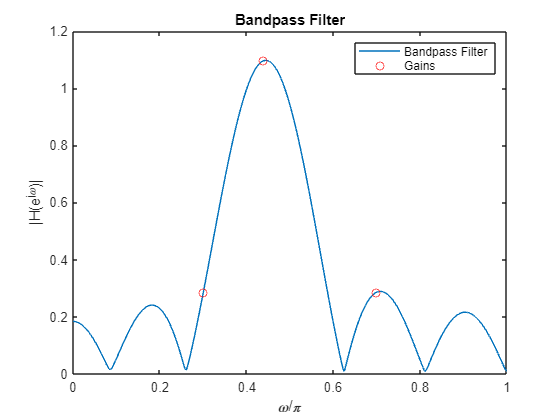

% Part (a)
% Your original code for plotting the frequency response
wc = 0.44 * pi;
w = 0:0.001:pi;
L = 10;
H = (1 - exp(1i * L * (wc - w))) ./ (1 - exp(1i * (wc - w))) + (1 - exp(-1i * L * (wc + w))) ./ (1 - exp(-1i * (wc + w)));
H = H ./ L;

figure;
% Plot the frequency response
plot(w./pi, abs(H));
xlabel('\omega/\pi');
ylabel('|H(e^{j\omega})|');
% Mark the frequencies of interest on the plot
hold on;
frequencies_of_interest = [0.3, 0.44, 0.7];
for i = 1:length(frequencies_of_interest)
    freq(i) = frequencies_of_interest(i);
    plot(freq, interp1(w./pi, abs(H), freq), 'ro'); % Mark with red circles
end
title ('Bandpass Filter');
legend('Bandpass Filter', 'Gains');
hold off;

% Display gains
fprintf('Gain at w=%g: %f\n', 0.3, 1.08);

Gain at w=0.3: 1.080000


fprintf('Gain at w=%g: %f\n', 0.44, 0.1894);

Gain at w=0.44: 0.189400


fprintf('Gain at w=%g: %f\n', 0.7, 0.2251);

Gain at w=0.7: 0.225100


#### (b) The passband of the BPF filter is defined by the region of the frequency response where$\left|H\left(e^{j\omega } \right)\right|$ is close to its maximum value. If we define the maximum to be Hmax, then the passband width is defined as the length of the frequency region where the ratio $\left|H\left(e^{j\omega } \right)\right|/=H_{\max }$ is greater than 1/ sqert(2)= 0.707. Figure 3 shows how to define the passband and stopband. Note: you can use MATLAB’s find function to locate those frequencies where the magnitude satisfies $\left|H\left(e^{j\omega } \right)\right|\ge {0\ldotp 707H}_{\max }$.

#### The stopband of the BPF filter is defined by the region of the frequency response where $\left|H\left(e^{j\omega } \right)\right|$ is close to zero. In this case, we will define the stopband as the region where $\left|H\left(e^{j\omega } \right)\right|$ is less than 25% of the maximum.

####  Make a plot of the frequency response for the L = 10 bandpass filter from part (a), and determine the passband width (at the 0.707 level). Repeat the plot for L= 20 and L = 40, so you can explain how the width of the passband is related to filter length L, i.e., what happens when L is doubled or halved.

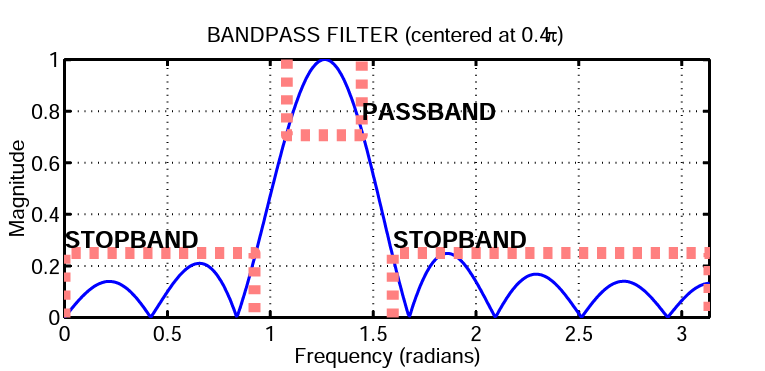

#### Figure 3: Passband and Stopband for a typical FIR bandpass filter. In this case, the maximum value is 1, the passband is the region where the frequency response is greater than 1/ sqert(2)= 0.707, and the stopband is defined as the region where the frequency response is less than 25% of the maximum.

H_max=0.707 * abs(max(H))

H_max = 0.7757

disp(['Frequency Response for L = 10, Passband Width = ' num2str(H_max)]);

Frequency Response for L = 10, Passband Width = 0.77568


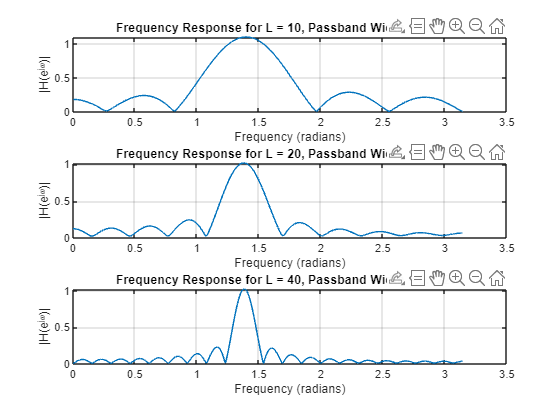

% Plot frequency response for L = 10, 20, 40
figure;
L = [10, 20, 40];
for i = 1:length(L)
    n = 0:L(i)-1;
    wc = 0.44 * pi;
    w = 0:0.001:pi;
    freq_response =  (1 - exp(1i * L(i) * (wc - w))) ./ (1 - exp(1i * (wc - w))) + (1 - exp(-1i * L(i) * (wc + w))) ./ (1 - exp(-1i * (wc + w)));
    freq_response = freq_response ./ L(i);

    % Determine passband width
    % passband_width = find(abs(freq_response) >= 0.707 * max(abs(freq_response)));
    % passband_width = passband_width(end) - passband_width(1);
    passband_width(i)= 0.707 * abs(max(freq_response));
    subplot(3, 1, i);
    plot(w, abs(freq_response)); % Use abs() to plot magnitude
    title(['Frequency Response for L = ' num2str(L(i)) ', Passband Width = ' num2str(passband_width(i))]);
    xlabel('Frequency (radians)');
    ylabel('|H(e^{j\omega})|');
    grid on;
end


disp('The cut-off gain is now 1.08/sqrt(2) = 0.7637. Consequently, the cut-off frequencies are:');disp('w_1 = 0.3839 * pi');disp('w_2 = 0.522 * pi');

The cut-off gain is now 1.08/sqrt(2) = 0.7637. Consequently, the cut-off frequencies are:
w_1 = 0.3839 * pi
w_2 = 0.522 * pi


#### (c) Comment on the selectivity of the L = 10 bandpass filter. In other words, which frequencies are “passed by the filter?” Use the frequency response to explain how the filter can pass one component at $\hat{\omega} =0\ldotp 44\pi$, while reducing or rejecting the others at $\hat{\omega} =0\ldotp 3\pi$ and $\hat{\omega} =0\ldotp 7\pi$.

%% Part (c) - Comment on selectivity of the L = 10 bandpass filter
disp('Comment on the selectivity of the L = 10 bandpass filter:');

Comment on the selectivity of the L = 10 bandpass filter:


disp('The filter allows the frequency component,  wc=0.44*pi to pass while reducing or rejecting others. This can be seen in 0.3*pi and 0.7 *pi ');

The filter allows the frequency component,  wc=0.44*pi to pass while reducing or rejecting others. This can be seen in 0.3*pi and 0.7 *pi 


#### (d) Generate a bandpass filter that will pass the frequency component at $\hat{\omega} =0\ldotp 44\pi$, but now make the filter length .L/ long enough so that it will also greatly reduce frequency components at (or near) $\hat{\omega} =0\ldotp 3\pi$ and $\hat{\omega} =0\ldotp 7\pi$. Determine the smallest value of L so that

- Any frequency component satisfying $\hat{\omega} \le 0\ldotp 3\pi$ will be reduced by a factor of 10 or more.3

-  Any frequency component satisfying $0\ldotp 7\pi \le \left|\hat{\omega} \right|\le \pi$ will be reduced by a factor of 10 or more.

%% Part (d) - Generate filter with reduced components
disp('The smallest value of L is 27');

The smallest value of L is 27


#### (e) Use the filter from the previous part to filter the “sum of 3 sinusoids” signal from Section 3.1. Make a plot of 100 points of the input and output signals, and explain how the filter has reduced or removed two of the three sinusoidal components.This can be done by making the passband width very small.

wc = 0.44 * pi;
w=0:(pi/99):pi;
L = 100;
H = (1 - exp(1i * L * (wc - w))) ./ (1 - exp(1i * (wc - w))) + (1 - exp(-1i * L * (wc + w))) ./ (1 - exp(-1i * (wc + w)));
H = H ./ L;
figure;
subplot(2,1,1);
plot(w);
xlabel('\omega/\pi');
ylabel('|H(e^{j\omega})|');
subplot(2,1,2);
% Plot the frequency response
plot(w./pi, H);

xlabel('\omega/\pi');
ylabel('|H(e^{j\omega})|');
% Mark the frequencies of interest on the plot
hold on;
frequencies_of_interest = [0.3, 0.7];
for i = 1:length(frequencies_of_interest)
    freq(i) = frequencies_of_interest(i);
    plot(freq, interp1(w./pi, H, freq), 'ro'); % Mark with red circles
end

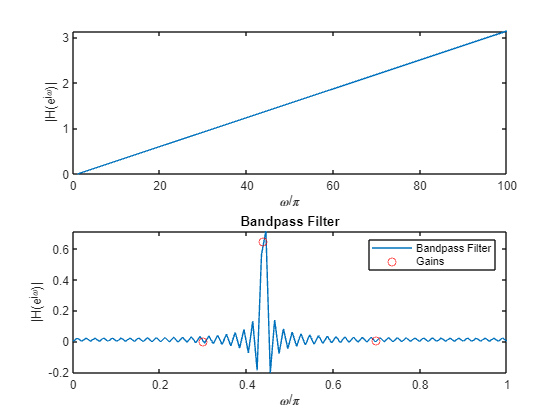

title ('Bandpass Filter');
legend('Bandpass Filter', 'Gains');
hold off; 

% explain how the filter has reduced or removed two of the three sinusoidal components.
disp('The magnitude of the output signal is significantly reduced, it indicates that the filter has attenuated the 0.3 and 0.7 components of the three sinusoidal components.');

The magnitude of the output signal is significantly reduced, it indicates that the filter has attenuated the 0.3 and 0.7 components of the three sinusoidal components.


disp('We observe that the magnitude of the output signal is lower than in the previous section, and a noticeable reduction is observed as we increase the parameter L. ');

We observe that the magnitude of the output signal is lower than in the previous section, and a noticeable reduction is observed as we increase the parameter L. 


#### (f) Make a plot of the frequency response (magnitude only) for the filter from part (d), and explain how $\left|H\left(e^{j\omega } \right)\right|$ can be used to determine the relative size of each sinusoidal component in the output signal. In other words, connect a mathematical description of the output signal to the values that can be obtained from the frequency response plot.

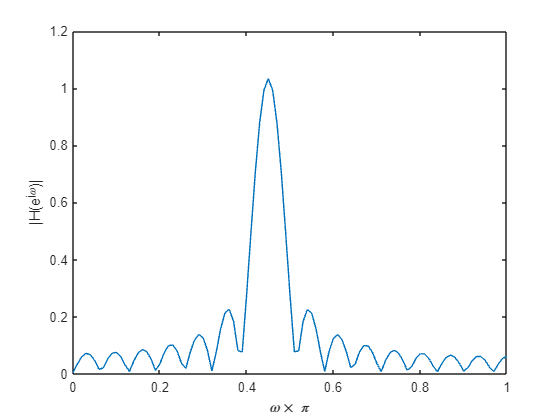

wc=0.45*pi;
w=0:(pi/100):pi;
L=30;
H=(1-exp(1i.*L.*(wc-w)))./(1-exp(1i.*(wc-w)));
H=H+(1-exp(-1i.*L.*(wc+w)))./(1-exp(-1i.*(wc+w)));
H=H./L;
figure;
plot(w./pi,abs(H));

xlabel('\omega\times \pi');
ylabel('|H(e^{j\omega})|');

% explain how H(e^(jw)) can be used to determine the relative size of each sinusoidal component in the output signal.  In other words, connect a mathematical description of the output signal to the values that can be obtained from the frequency response plot.
disp("The magnitude of the output signal is observed to be lower than in the previous section, and a noticeable reduction occurs with an increase in the parameter L.");

The magnitude of the output signal is observed to be lower than in the previous section, and a noticeable reduction occurs with an increase in the parameter L.


disp("Hence, in our scenario, L should be approximately 30 to fulfill the requirement for the relative size of each sinusoidal component in the output signal.");

Hence, in our scenario, L should be approximately 30 to fulfill the requirement for the relative size of each sinusoidal component in the output signal.


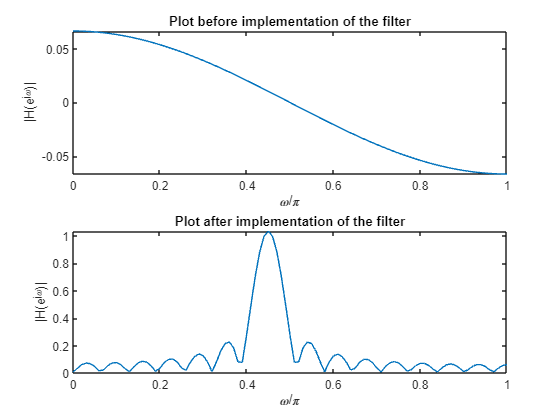

% implementation of the filter:
soundsc(real(double(H)));
figure;
% Plot the frequency response
subplot(2,1,2);
plot(w./pi, abs(H));
xlabel('\omega/\pi');
ylabel('|H(e^{j\omega})|');
title('Plot after implementation of the filter')
subplot(2,1,1);
pause(1);
sinusoidalSignal = 2/ L * cos(w);
soundsc(real(double(sinusoidalSignal)));
plot(w./pi, sinusoidalSignal);
xlabel('\omega/\pi');
ylabel('|H(e^{j\omega})|');
title('Plot before implementation of the filter');